# Remove Noise with a Linear Filter

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

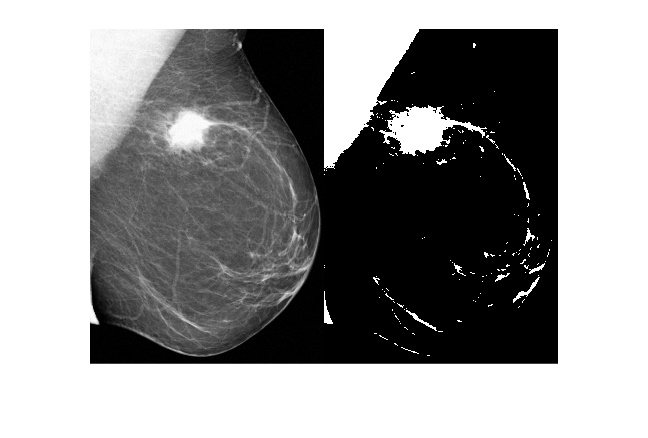

tumor = readmatrix("./images/tumorReducedSize.csv", OutputType="uint8");
tumorBW = imbinarize(tumor);
imshowpair(tumor, tumorBW, "montage")

## Task 1

You can create a filter using the `fspecial` function.

`filt` `=` `fspecial``(``"type"``,``filterSize``)`

You can use a 2-element vector for `filterSize` to define a rectangular window. An `"average"` filter replaces each pixel with the average of the pixels in the window around it.

filterSize = [3 3];
avg = fspecial("average", filterSize);

## Task 2

You can use `imfilter` to filter an image with a specified filter.

`imFiltered` `=` `imfilter``(``im``,``filt``)``;`

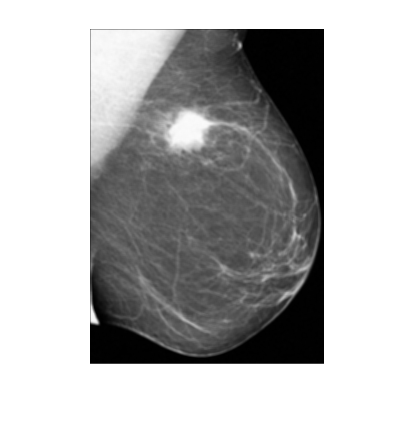

tumorAvg = imfilter(tumor, avg);
imshow(tumorAvg)

## Task 3

Notice that the edges of `tumorAvg` are dark, even in the upper left where the edges used to be white. This is because edge pixels don't have a full neighborhood around them. By default `imfilter` pads the boundary with zeros. This darkens the edges.

You can specify a different boundary padding method as a third input to `imfilter`. The  `"symmetric"` method reflects the array across the border.

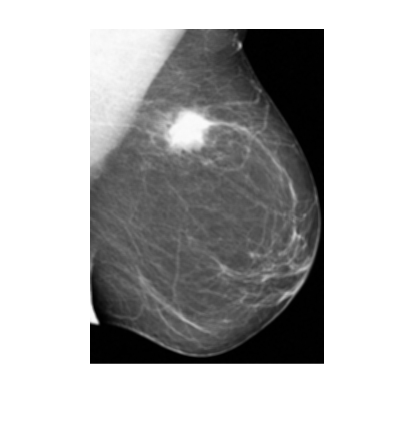

tumorAvg = imfilter(tumor, avg, "symmetric");
imshow(tumorAvg)

## Task 4

The goal of this preprocessing was to create a better segmentation of the tumor.

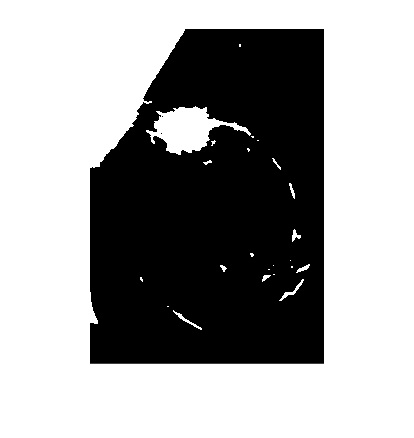

tumorAvgBW = imbinarize(tumorAvg);
imshow(tumorAvgBW)

## Task 5

The new segmentation is cleaner, but at the cost of making the image slightly blurry. When you used an averaging filter to smooth the image, you removed both noise and some detail.

Using a different filter size will change the appearance of the filtered image and the quality of the segmentation.

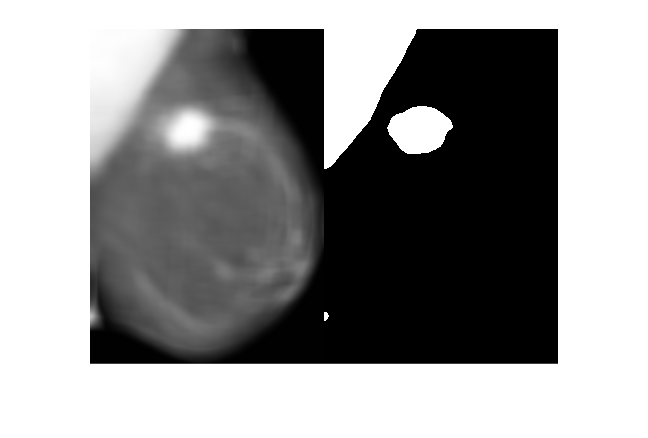

filterSize = [15 15];
avg = fspecial("average", filterSize);
tumorAvg = imfilter(tumor, avg, "symmetric");
tumorAvgBW = imbinarize(tumorAvg);
imshowpair(tumorAvg, tumorAvgBW, "montage")